clearvars, clc;

wavelength = (1530 : 0.1 : 1594-0.1) .* 1e-9; % nm
c = 299792458;
t = (0 : 0.1 : 100-0.1) .* 1e-9; % ns
[B, H] = JonesMatrix(wavelength, t);
N = length(B);

T = zeros(2*length(t), 2*length(wavelength));
for tindex = 1 : length(t)
    for windex = 1 : length(wavelength)
        % 计算填充的T
        Ttemp= H{N+1}(:, 2*tindex-1: 2*tindex);
        for i = N : -1 : 1
            Ttemp = Ttemp * B{i}(:, 2*windex-1: 2*windex);
            Ttemp = Ttemp * H{i}(:, 2*tindex-1: 2*tindex);
        end
        T(2*tindex-1: 2*tindex, 2*windex-1: 2*windex) = Ttemp;
    end
end

Q = zeros(length(T), width(T)-2);
tau = struct('modulus', zeros(2, 2), 'phat', []);
tau.phat = struct('direction',num2cell(zeros(length(t), length(wavelength), 3), 3));
vec_tau = cell(3, 1);
vec_tau{1} = zeros(length(t), length(wavelength)-1);
vec_tau{2} = zeros(length(t), length(wavelength)-1);
vec_tau{3} = zeros(length(t), length(wavelength)-1);
FOPMD = zeros(length(T)/2, width(T)/2-1);
for tindex = 1 : (length(T)/2)
    for windex = 1 : (width(T)/2 - 1)
        df = c./wavelength(windex) - c./wavelength(windex+1);
        dw = 2*pi*df;
        dT = T(2*tindex-1: 2*tindex, 2*windex+1: 2*windex+2) - T(2*tindex-1: 2*tindex, 2*windex-1: 2*windex);
        dT = dT ./ dw;
        Q(2*tindex-1: 2*tindex, 2*windex-1: 2*windex) = 1j * dT * T(2*tindex-1: 2*tindex, 2*windex-1: 2*windex)';
        vec_tau{1}(tindex, windex) = real( Q(2*tindex-1, 2*windex-1) - Q(2*tindex, 2*windex) );
        vec_tau{2}(tindex, windex) = real( Q(2*tindex-1, 2*windex) + Q(2*tindex, 2*windex-1) );
        vec_tau{3}(tindex, windex) = real( 1j * (Q(2*tindex, 2*windex-1) - Q(2*tindex-1, 2*windex)) );
        temp = [vec_tau{1}(tindex, windex), vec_tau{2}(tindex, windex), vec_tau{3}(tindex, windex)];
        FOPMD(tindex, windex) = norm(temp, 2);
        tau.modulus(tindex, windex) = FOPMD(tindex, windex);
        tau.phat(tindex, windex).direction = temp ./ FOPMD(tindex, windex);
    end
end

SOPMD = zeros(length(FOPMD), width(FOPMD)-1);
dvec_tau = zeros(3, 1000);
for i = 1 : width(SOPMD)
    df = c./wavelength(i) - c./wavelength(i+1);
    dw = 2*pi*df;
    dvec_tau(1, :) = (vec_tau{1}(:, i+1) - vec_tau{1}(:, i)) ./ dw;
    dvec_tau(2, :) = (vec_tau{2}(:, i+1) - vec_tau{2}(:, i)) ./ dw;
    dvec_tau(3, :) = (vec_tau{3}(:, i+1) - vec_tau{3}(:, i)) ./ dw;
    for tindex = 1 : length(SOPMD)
        SOPMD(tindex, i) = norm(dvec_tau(:, tindex), 2);
    end
end

## PCD

PCD = zeros(length(FOPMD), width(FOPMD)-1);
for windex = 1 : width(PCD)
    df = c./wavelength(windex) - c./wavelength(windex+1);
    dw = 2*pi*df;
    for tindex = 1 : length(t)
        PCD(tindex, windex) = (FOPMD(tindex, windex+1) - FOPMD(tindex, windex)) ./ dw;
    end
end

## depolarizaion

depolarizaion = zeros(length(FOPMD), width(FOPMD)-1);
for windex = 1 : width(PCD)
    df = c./wavelength(windex) - c./wavelength(windex+1);
    dw = 2*pi*df;
    for tindex = 1 : length(t)
        dp = (tau.phat(tindex, windex+1).direction - tau.phat(tindex, windex).direction);
        depolarizaion(tindex, windex) = FOPMD(tindex, windex) * norm(dp ./ dw, 2);
    end
end

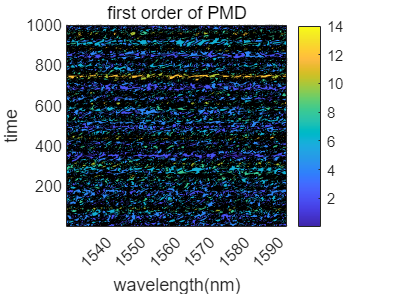

FOPMD = FOPMD .* 1e12; % ps
figure
contourf(FOPMD); %ps
LevelList = [6, 5, 4, 3, 2, 1];
colorbar
set(gca, 'XTick', 100 : 100: 900, 'XTickLabel', [1540, 1550, 1560, 1570, 1580, 1590]);
xlabel('wavelength(nm)')
ylabel('time')
title('first order of PMD')

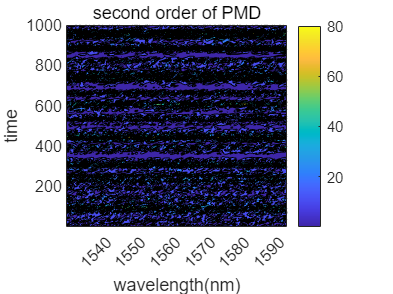

SOPMD = SOPMD .* 1e24; % ps^2
figure
contourf(SOPMD); %ps
LevelList = [6, 5, 4, 3, 2, 1];
colorbar
set(gca, 'XTick', 100 : 100: 900, 'XTickLabel', [1540, 1550, 1560, 1570, 1580, 1590]);
xlabel('wavelength(nm)')
ylabel('time')
title('second order of PMD')

## Draw a probability distribution for DGD

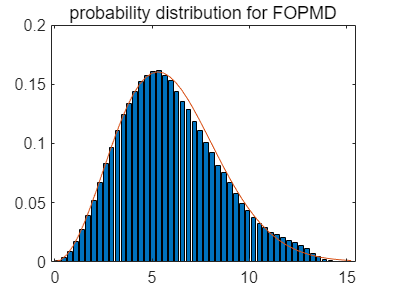

cnt = length(t);
f_rf = width(wavelength);
FOPMD=reshape(FOPMD,1,cnt*(f_rf-1));
figure
[rr_freq, x_centers] = hist(FOPMD,50);       % [The number of statistics for each interval，The center coordinates]           
lengthwin=((max(FOPMD(:))-min(FOPMD(:)))/length(rr_freq));
rr_pdf = rr_freq./sum(rr_freq(:))/lengthwin;       %rr_freq is the number of occurrences,sum(rr_pdf)*lengthwin=1
bar(x_centers,rr_pdf);
hold on
x = linspace(0,max(FOPMD),length(rr_freq));
meantao = mean(FOPMD);
y = 32*x.^2.*exp(-(4*x.^2)/(pi*meantao.^2))/(pi.^2*meantao.^3);  %% Theory,References: Polarization Optics in Telecommunications PP-402
y=y./sum(y)/lengthwin;  
plot(x,y)
title('probability distribution for FOPMD')

## Draw a probability distribution for SOPMD

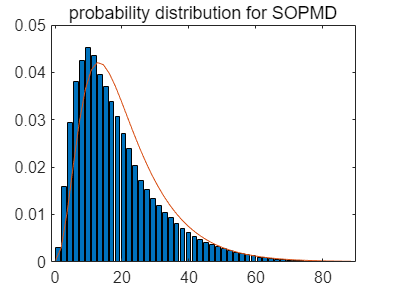

PMD2order_seq = SOPMD;
PMD2order_seq=reshape(PMD2order_seq,1,cnt*(f_rf-2));
figure
[rr_freq, x_centers] = hist(PMD2order_seq,50);              
lengthwin=((max(PMD2order_seq(:))-min(PMD2order_seq(:)))/length(rr_freq));
rr_pdf = rr_freq./sum(rr_freq(:))/lengthwin;
bar(x_centers,rr_pdf);
hold on
x = linspace(0,max(PMD2order_seq),length(rr_freq));
y = 32*x.*tanh(4*x/meantao^2).*sech(4*x/meantao^2)/(pi*meantao^4);  %% Theory,References: Polarization Optics in Telecommunications PP-402% Theory
y=y./sum(y)/lengthwin; 
plot(x, y)
title('probability distribution for SOPMD')

## Draw a probability distribution for PCD

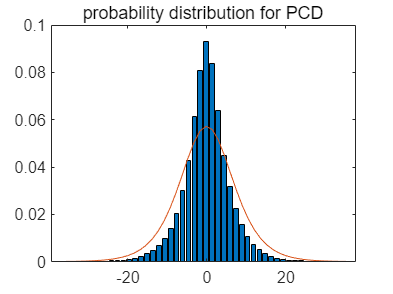

figure
PCD = PCD .* 1e24;
PCDvalue_seq = reshape(PCD,1,cnt*(f_rf-2));
[rr_freq, x_centers] = hist(PCDvalue_seq,50);              
lengthwin=((max(PCDvalue_seq(:))-min(PCDvalue_seq(:)))/length(rr_freq));
rr_pdf = 1*rr_freq./sum(rr_freq(:))/lengthwin;
bar(x_centers,rr_pdf);
hold on
x = linspace(min(PCDvalue_seq),max(PCDvalue_seq),length(rr_freq));
y = 2*(sech(4*x/meantao^2)).*(sech(4*x/meantao^2))/(meantao^2);      %% Theory,References: Polarization Optics in Telecommunications PP-402
y=y./sum(y)/lengthwin;
plot(x,y)
title('probability distribution for PCD')

## Draw a probability distribution for depolarizaion

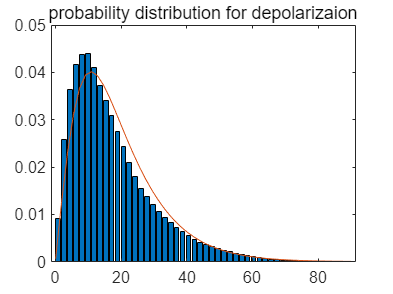

depolarizaion = depolarizaion .* 1e24;
depolarizaion_seq = reshape(depolarizaion,1,cnt*(f_rf-2));
figure
[rr_freq, x_centers] = hist(depolarizaion_seq,50);              
lengthwin=((max(depolarizaion_seq(:))-min(depolarizaion_seq(:)))/length(rr_freq));
rr_pdf = 1*rr_freq./sum(rr_freq(:))/lengthwin;
bar(x_centers,rr_pdf);
hold on
x = linspace( min(depolarizaion_seq) , max(depolarizaion_seq),length(rr_freq));
alpha = 0:0.001:100;
dalpha = alpha(2)-alpha(1);
for i = 1:length(x)
y(i) =  x(i)*(8/(pi*meantao^2))^2 * dalpha *sum( besselj( 0, 8*x(i)*alpha/pi/meantao^2 ).*sech(alpha).*sqrt( alpha.*tanh(alpha)) ) ;   %% Theory,References: Polarization Optics in Telecommunications PP-402
end
plot(x,y)
title('probability distribution for depolarizaion')

## ACF in time domain

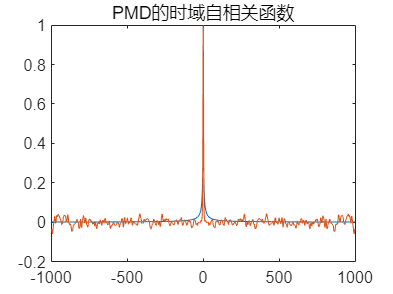

%% Frequency domain autocorrelation function of PMD
PMDtao1ACF=[];
deltal=[];      %Used to store frequency intervals Δw
claDGDc=FOPMD;
for i=1:length(wavelength)-1      %ACF(Δw)=E[Ω(w)*Ω(w+Δw)]
   [atPMDtao1c,deltal]=xcorr(vec_tau{1}(:,i),'unbiased');        %Calculates the autocorrelation function of tao1 at all frequency points
   PMDtao1ACF(i,:)=atPMDtao1c;
end
PMDtao2ACF=[];
deltal=[];
for i=1:length(wavelength)-1
   [atPMDtao2c,deltal]=xcorr(vec_tau{2}(:,i),'unbiased');        %Calculates the autocorrelation function of tao2 at all frequency points
   PMDtao2ACF(i,:)=atPMDtao2c;
end
PMDtao3ACF=[];
deltal=[];
for i=1:length(wavelength)-1
   [atPMDtao3c,deltal]=xcorr(vec_tau{3}(:,i),'unbiased');                 %Calculates the autocorrelation function of tao3 at all frequency points
   PMDtao3ACF(i,:)=atPMDtao3c;
end
meanPMDtao1ACF=mean(PMDtao1ACF);      %Take the average of time
meanPMDtao2ACF=mean(PMDtao2ACF);
meanPMDtao3ACF=mean(PMDtao3ACF);

middle=ceil(length(atPMDtao3c)/2);    %Normalize it by the value at Δw=zero       
meanPMDtao1ACF=meanPMDtao1ACF./(meanPMDtao1ACF(middle));
meanPMDtao2ACF=meanPMDtao2ACF./(meanPMDtao2ACF(middle));
meanPMDtao3ACF=meanPMDtao3ACF./(meanPMDtao3ACF(middle));
meanPMDtao=(meanPMDtao1ACF+meanPMDtao2ACF+meanPMDtao3ACF)/3;

td = abs(meanPMDtao-0.632);
td_min = min(td);
[row, col]=find(td==td_min);
td = td(row(1), col(1));

figure
% The theory of curve
pmdacf=(1-exp(-abs(deltal)/td)) ./ (abs(deltal)/td);    %The theoretical formula of frequency domain ACF
middle=floor(length(pmdacf)/2);
pmdacf=pmdacf./(pmdacf(middle));   %Normalization
plot(deltal,pmdacf)
hold on
plot(deltal,meanPMDtao)
title("PMD的时域自相关函数")

## ACF in frequency domain

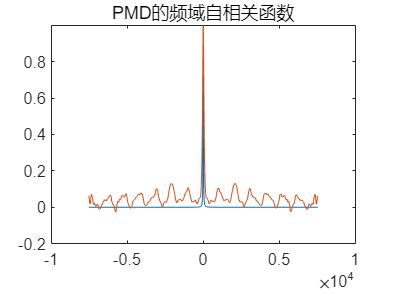

%% Frequency domain autocorrelation function of PMD
PMDtao1ACF=[];
deltal=[];      %Used to store frequency intervals Δw
claDGDc=FOPMD;
for i=1:cnt      %ACF(Δw)=E[Ω(w)*Ω(w+Δw)]
   [atPMDtao1c,deltal]=xcorr(vec_tau{1}(i,:),'unbiased');        %Calculates the autocorrelation function of tao1 at all frequency points
   PMDtao1ACF(i,:)=atPMDtao1c;
end
PMDtao2ACF=[];
deltal=[];
for i=1:cnt
   [atPMDtao2c,deltal]=xcorr(vec_tau{2}(i,:),'unbiased');        %Calculates the autocorrelation function of tao2 at all frequency points
   PMDtao2ACF(i,:)=atPMDtao2c;
end
PMDtao3ACF=[];
deltal=[];
for i=1:cnt
   [atPMDtao3c,deltal]=xcorr(vec_tau{3}(i,:),'unbiased');                 %Calculates the autocorrelation function of tao3 at all frequency points
   PMDtao3ACF(i,:)=atPMDtao3c;
end
meanPMDtao1ACF=mean(PMDtao1ACF);      %Take the average of time
meanPMDtao2ACF=mean(PMDtao2ACF);
meanPMDtao3ACF=mean(PMDtao3ACF);

middle=ceil(length(atPMDtao3c)/2);    %Normalize it by the value at Δw=zero       
meanPMDtao1ACF=meanPMDtao1ACF./(meanPMDtao1ACF(middle));
meanPMDtao2ACF=meanPMDtao2ACF./(meanPMDtao2ACF(middle));
meanPMDtao3ACF=meanPMDtao3ACF./(meanPMDtao3ACF(middle));
meanPMDtao=(meanPMDtao1ACF+meanPMDtao2ACF+meanPMDtao3ACF)/3;
figure
% The theory of curve
deltaomiga1=2*pi*deltal*df;
pmdacf=(3./(deltaomiga1.^2)).*(1-exp(-deltaomiga1.^2.*mean(claDGDc.^2)./3));    %The theoretical formula of frequency domain ACF
middle=floor(length(pmdacf)/2);
pmdacf=pmdacf./(pmdacf(middle));   %Normalization
plot(deltal*df/1e9,pmdacf)
hold on
plot(deltal*df/1e9,meanPMDtao)
title("PMD的频域自相关函数")